T = readtable('resulting_data.csv')

T = 19×5 table
    NumberOfRetweets    NumberOfReplies    PositiveScore    NegativeScore    NetScore
    ________________    _______________    _____________    _____________    ________

            3                  0                 0                0              0   
            1                  0                 2                2              0   
            1                  2                 1                0              1   
            3                  1                 1                0              1   
            6                  0                 2                0              2   
            9                  5                 2                0              2   
           19                  0                 2                0              2   
            0                  0        

T = T{:,:}

T =      3     0     0     0     0
     1     0     2     2     0
     1     2     1     0     1
     3     1     1     0     1
     6     0     2     0     2
     9     5     2     0     2
    19     0     2     0     2
     0     0     0     3    -3
     0     0     0     2    -2
    82     2     4     0     4




Num = T(:,1)

Num =      3
     1
     1
     3
     6
     9
    19
     0
     0
    82


Net = T(:,end)

Net =      0
     0
     1
     1
     2
     2
     2
    -3
    -2
     4


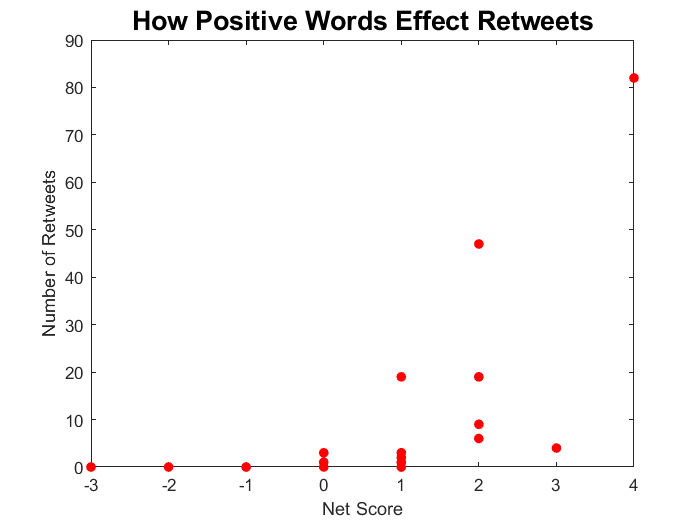


plot(Net,Num,'.r','MarkerSize', 20)
title('How Positive Words Effect Retweets','FontSize',16);
xlabel("Net Score")
ylabel("Number of Retweets")